## Exercise 1: Moving Average filter

### 4 Taps

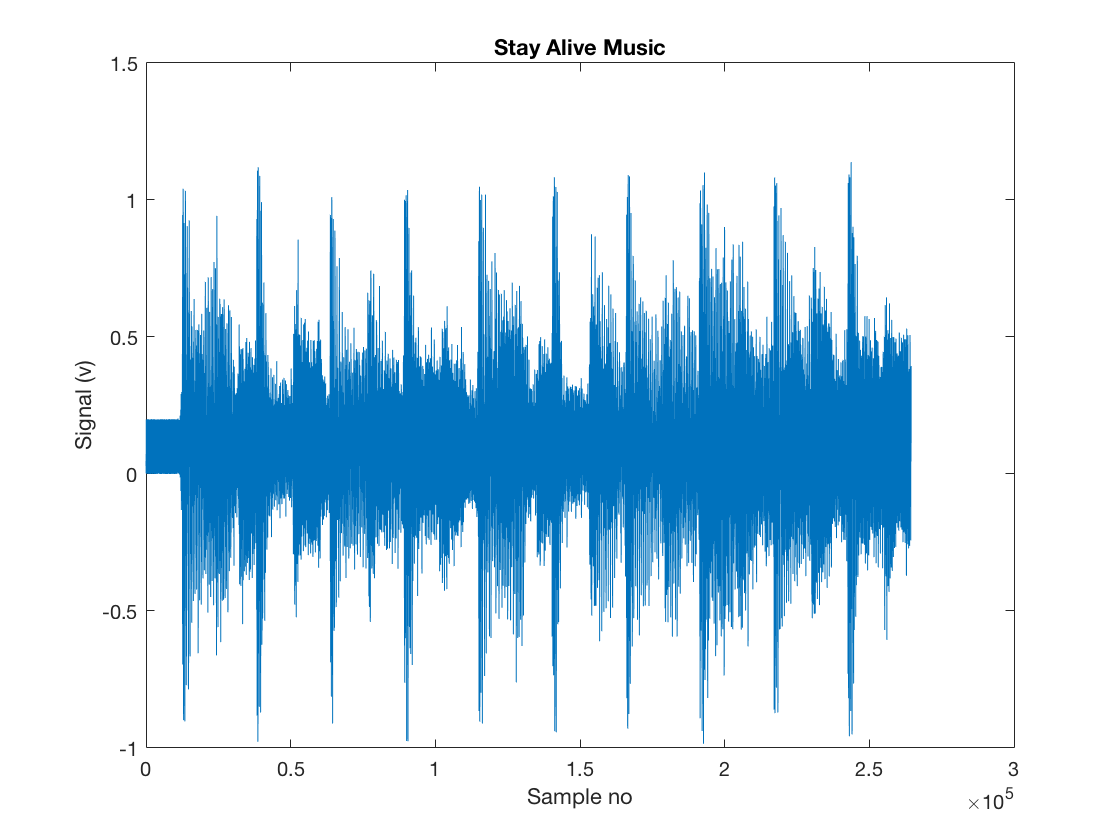

% Lab 5 - Ex 5a: 4-taps Movng average filter
% The inefficient way
[sig fs] = audioread('bgs.wav');
% Add noise to music
x = sig + 0.2*rand(size(sig));
% Plot the signal
figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');

% Filter music with moving average filter
N = size(x);
for i=4:N
    y1(i) = (x(i) + x(i-1) + x(i-2) + x(i-3)) / 4;
end
y1(1) = x(1) / 4;
y1(2) = (x(2) + x(1)) / 4;
y1(3) = (x(3) + x(2) + x(1)) / 4;
% Play the origional & then the filtered sound
sound(x, fs)
disp('Playing the original - press return when finished')

Playing the original - press return when finished


sound(y1, fs)
disp('Playing the filter music')

Playing the filter music


### 10 Taps

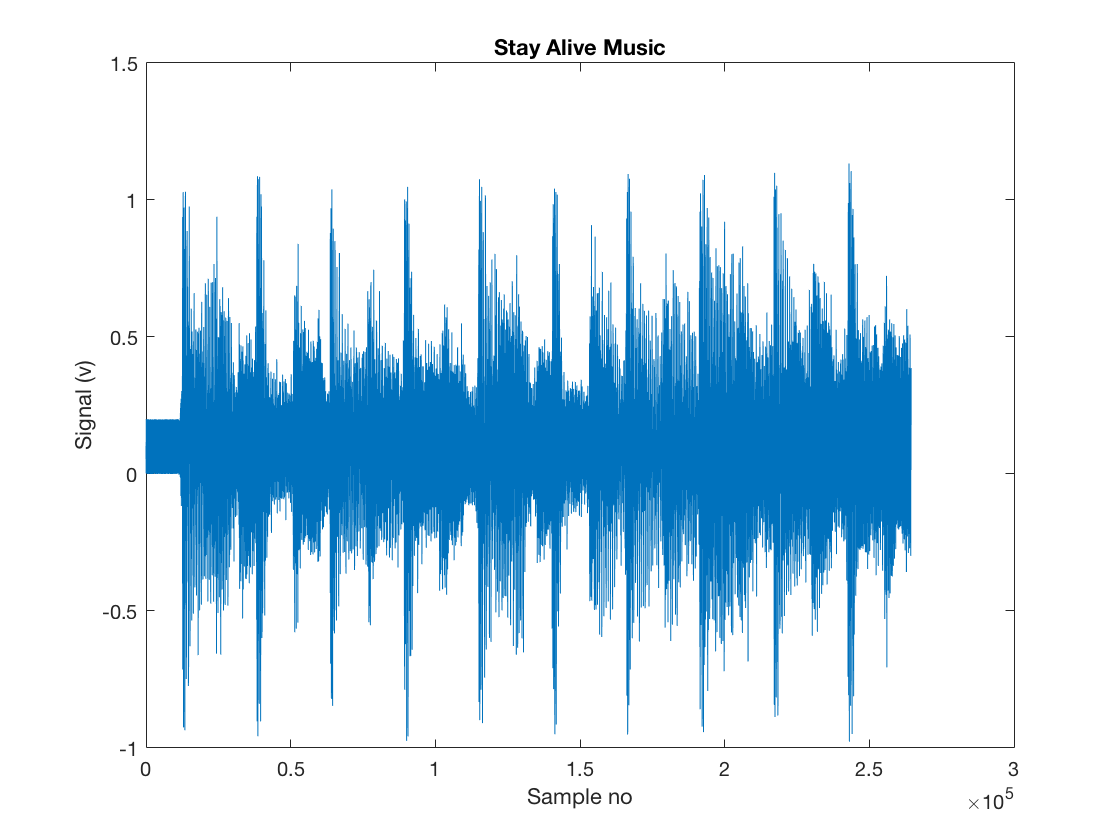

% Lab 5 - Ex 5a: 4-taps Movng average filter
% The inefficient way
[sig fs] = audioread('bgs.wav');
% Add noise to music
x = sig + 0.2*rand(size(sig));
% Plot the signal
figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');

% Filter music with moving average filter
N = size(x);
N_tap = 10

N_tap = 10

for i = 1:N
    y2(i) = 0;
    if i < N_tap
        for n = 0:i - 1
            y2(i) = y2(i) + x(i - n);
        end
        y2(i) = y2(i) / N_tap;
    else
        for n = 0:N_tap - 1
            y2(i) = y2(i) + x(i - n);
        end
        y2(i) = y2(i) / N_tap;
    end
end
% Play the origional & then the filtered sound
sound(x, fs)
disp('Playing the original - press return when finished')

Playing the original - press return when finished


sound(y2, fs)
disp('Playing the filter music')

Playing the filter music


### 20 Taps

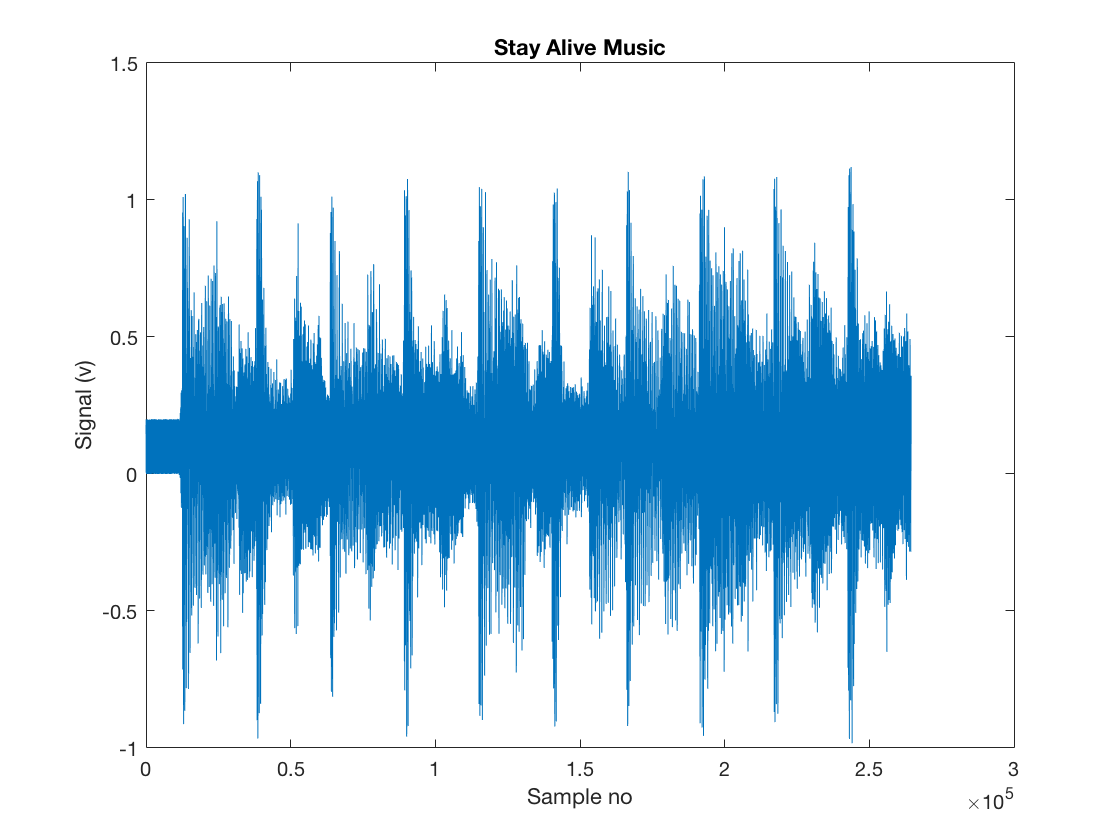

% Lab 5 - Ex 5a: 4-taps Movng average filter
% The inefficient way
[sig fs] = audioread('bgs.wav');
% Add noise to music
x = sig + 0.2*rand(size(sig));
% Plot the signal
figure(1);
clf;
plot(x);
xlabel('Sample no');
ylabel('Signal (v)');
title('Stay Alive Music');

% Filter music with moving average filter
N = size(x);
N_tap = 20;

N_tap = 20

for i = 1:N
    y3(i) = 0;
    if i < N_tap
        for n = 0:i - 1
            y3(i) = y3(i) + x(i - n);
        end
        y3(i) = y3(i) / N_tap;
    else
        for n = 0:N_tap - 1
            y3(i) = y3(i) + x(i - n);
        end
        y3(i) = y3(i) / N_tap;
    end
end
% Play the origional & then the filtered sound
sound(x, fs)
disp('Playing the original - press return when finished')

Playing the original - press return when finished


sound(y3, fs)
disp('Playing the filter music')

Playing the filter music
